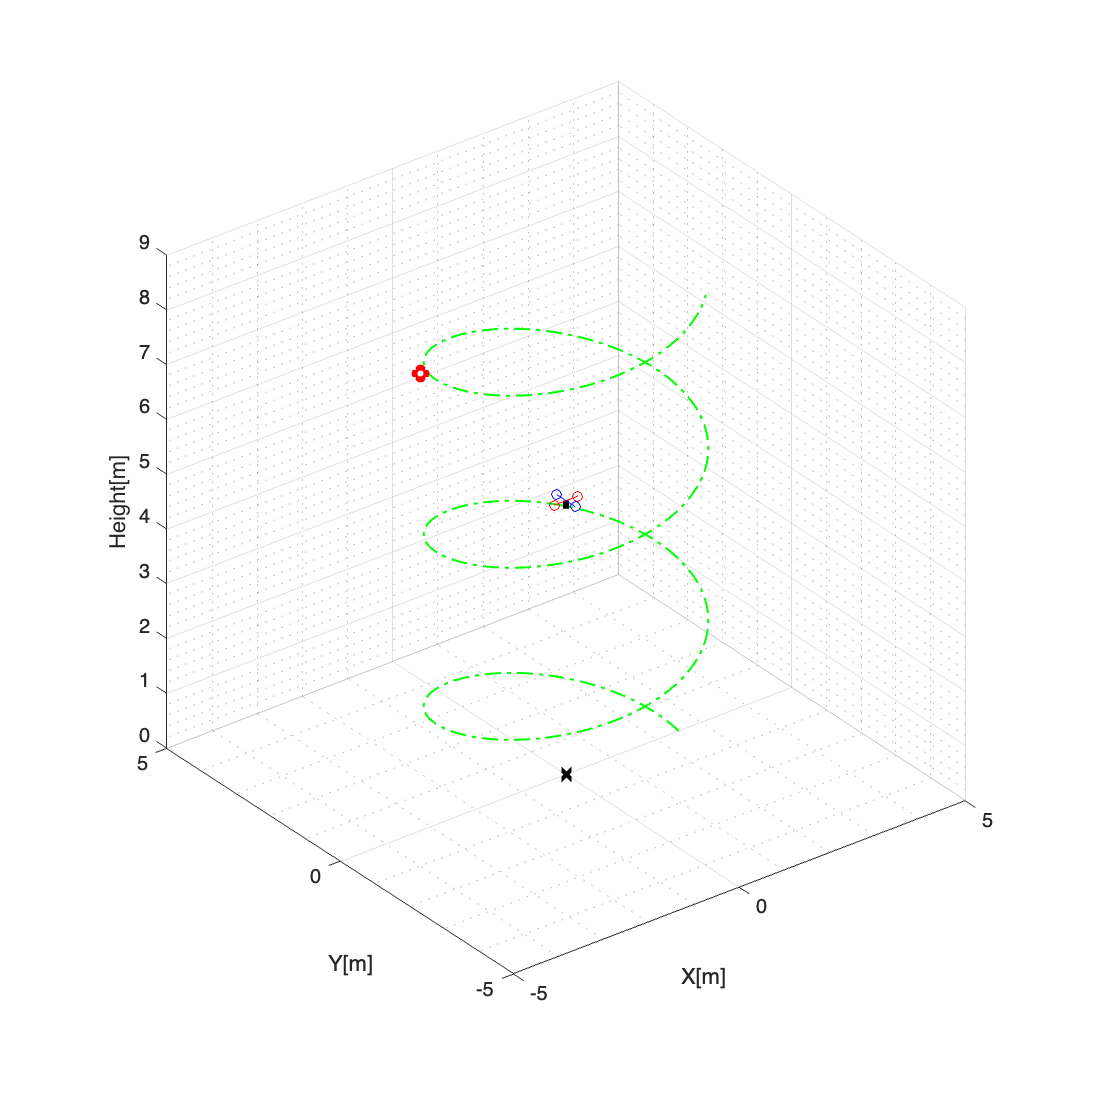

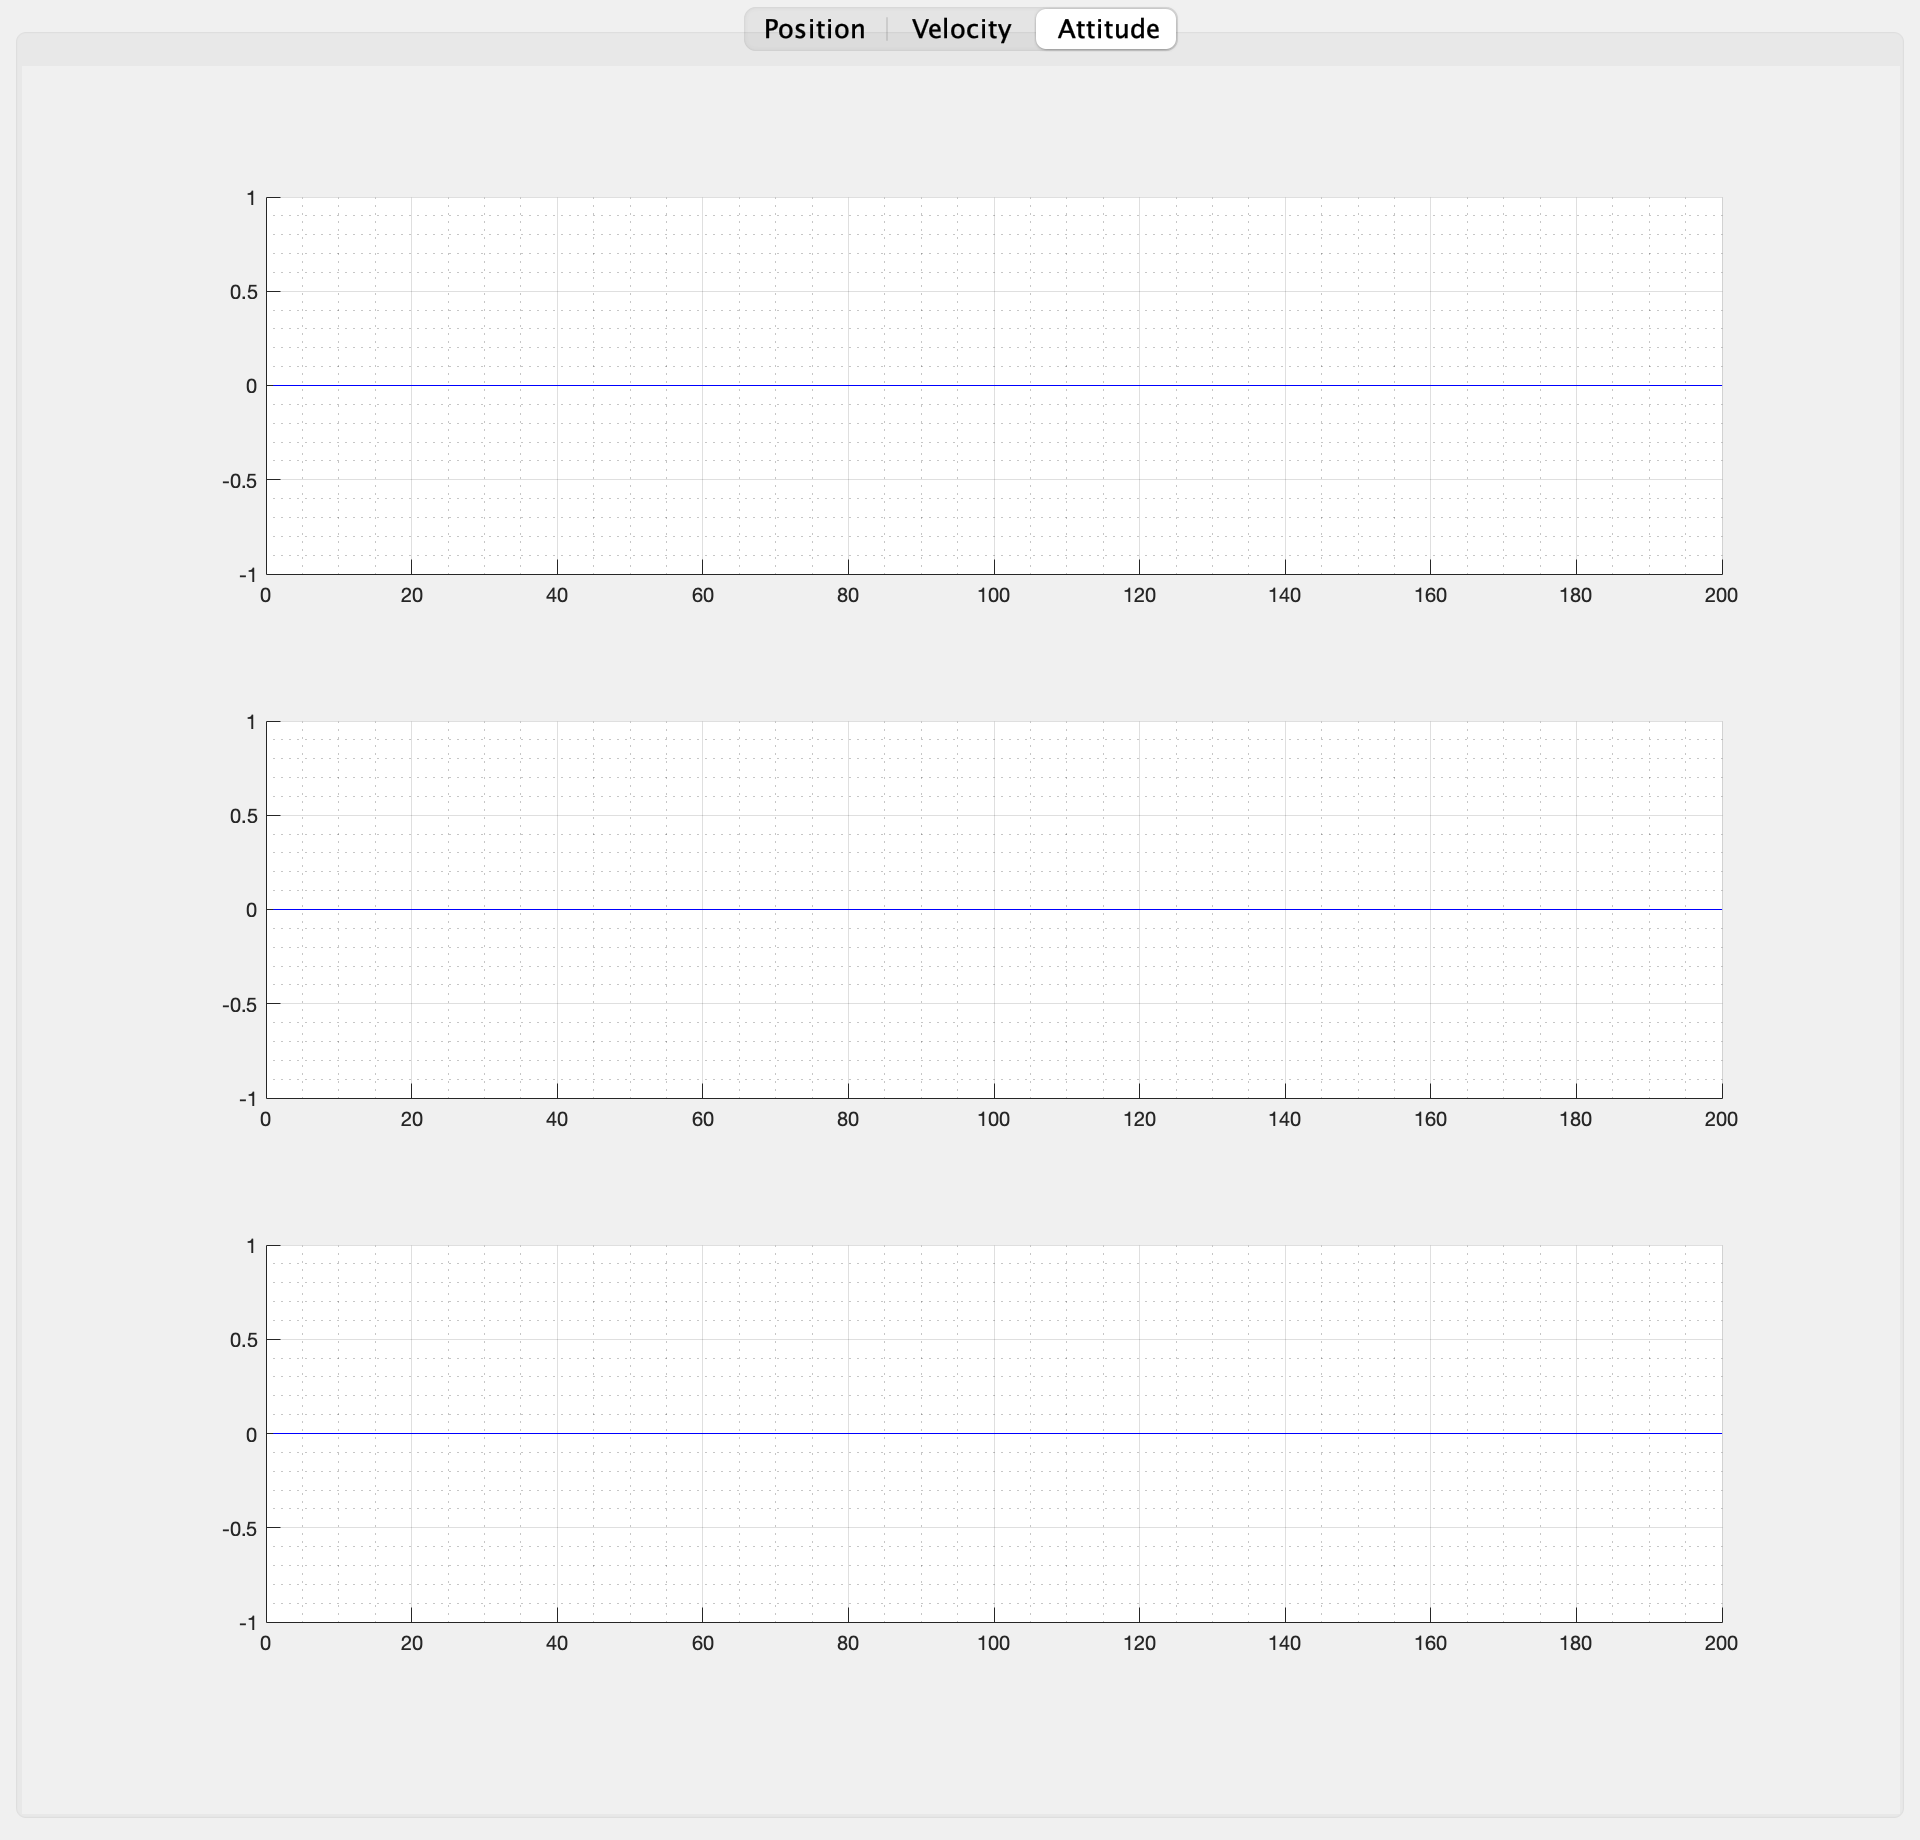

close all;
clc; clear;
clearvars;
addpath('./lib')

%% DEFINE
R2D = 180/pi;
D2R = pi/180;

%% INIT. PARAMS.

% drone_params = containers.Map({'mass','gyro','inertialMatrix'},...
%     {0.467, [0.2, 0.1, -0.1]',diag([8.28, 8.28, 15.7]*10^-3)});

drone_params = containers.Map({'mass','gyro','inertialMatrix'},...
    {0.467, [0, 0, 0]',diag([8.28, 8.28, 15.7]*10^-3)});

drone_initStates = containers.Map({'position','velocity','attitude','angularV' }, ...
    {[0, 0, 5]',[0,0,0]',eye(3),zeros(3,1)}); 



drone_initInputs = [0, 0, 0, 0]';                                                                  % R, P, Y CMD

drone_body = [ 0.265,      0,     0, 1; ...
                    0, -0.265,     0, 1; ...
               -0.265,      0,     0, 1; ...
                    0,  0.265,     0, 1; ...
                    0,      0,     0, 1; ...
                    0,      0, -0.15, 1]';
			  

%% BIRTH OF A DRONE

simulationTime = 2;  
drone = Drone(drone_params, drone_initStates, drone_initInputs,simulationTime);


%% Simulation time


ts = 0.1;
t = 0:ts:120;


%% desired trajectory
% ****** Example 01 *******
xrd = 2.5*cos(0.2*t);
yrd = 2.5*sin(0.2*t);
zrd = 0.1*t;

% trajectoryD = [xrd, yrd, zrd]';

% ****** Example 02 *******
% xrd = 2.5*cos(0.2*t);
% yrd = 2.5*sin(0.4*t);
% zrd = 7*ones(1,length(t));

%% desired position

xd = randi([-5 5]);
yd = randi([-5 5]);
zd = randi([0 9]);

positionD = [xd, yd, zd]';

%% Starting simulation

figure('position',[0 200 800 800]);
 view(3);
% view([-60 30]);
% view([90 0])   % To check phi (roll attitude) only
% view([0 0])    % To check theta (pitch attitude) only
% view([270 90]) % Top view

axis square; 
grid on;
grid minor;
axis([-5 5 -5 5 0 9]);
xlabel('X[m]');
ylabel('Y[m]');
zlabel('Height[m]');


hold(gca,'on');

%% Creating 3d model of the drone

drone1_state = drone.GetState();
wHb = [RPY2Rot([drone.phi, drone.theta, drone.psi])', drone1_state.s(1:3); 0 0 0 1];
% [Rot(also contains shear, reflection, local sacling), displacement; perspective ,global scaling]
drone1_world = wHb * drone_body; % [4x4][4x6]
drone1_atti = drone1_world(1:3, :); 
    
fig1_ARM13 = plot3(gca, drone1_atti(1,[1 3]), drone1_atti(2,[1 3]), drone1_atti(3,[1 3]), ...
        '-ro', 'MarkerSize', 5);
fig1_ARM24 = plot3(gca, drone1_atti(1,[2 4]), drone1_atti(2,[2 4]), drone1_atti(3,[2 4]), ...
        '-bo', 'MarkerSize', 5);
fig1_payload = plot3(gca, drone1_atti(1,[5 6]), drone1_atti(2,[5 6]), drone1_atti(3,[5 6]), ...
        '-k', 'Linewidth', 3);
fig1_shadow = plot3(gca,0,0,0,'xk','Linewidth',3);



%% Creating desired position or trajectory

 plot3(xd,yd,zd,'ro','LineWidth',3); % Draw desired position
 plot3(xrd,yrd,zrd,'g-.','LineWidth',1) % Draw the desired trajectory
drawnow

%% Creating plot of the variables

fig_handle = figure('Name','Drone state viewer','NumberTitle','off', ...
    'position',[960, 0, 960,1080]);
tg = uitabgroup;


position_tab = uitab(tg,'Title','Position');
axes('Parent',position_tab);

subplot(3,1,1);
grid on;
grid minor;
hold on;
subplot(3,1,2);
grid on;
grid minor;
hold on;
subplot(3,1,3);
grid on;
grid minor;
hold on;

velocity_tab = uitab(tg,'Title','Velocity');
axes('Parent',velocity_tab);

subplot(3,1,1);
grid on;
grid minor;
hold on;
subplot(3,1,2);
grid on;
grid minor;
hold on;
subplot(3,1,3);
grid on;
grid minor;
hold on;


attitude_tab = uitab(tg,'Title','Attitude');
axes('Parent',attitude_tab);

subplot(3,1,1);
grid on;
grid minor;
hold on;
subplot(3,1,2);
grid on;
grid minor;
hold on;
subplot(3,1,3);
grid on;
grid minor;
hold on;


%% Main Loop


timeF = [];

% Position
xt = [];
yt = [];
zt = [];

% Velocity
xvt = [];
yvt = [];
zvt = [];

% Attitude
rollt = [];
pitcht = [];
yawt = [];



for i = 1:simulationTime/0.01
    %% Take a step


    drone.AttitudeCtrl(positionD);
    drone.UpdateState();
	
	drone1_state = drone.GetState();
    
    %% 3D Plot
    figure(1)
    wHb = [RPY2Rot([drone.phi, drone.theta, drone.psi])', drone1_state.s(1:3); 0 0 0 1];
    drone1_world = wHb * drone_body;
    drone1_atti = drone1_world(1:3, :);

    xt(end+1) = drone1_state.s(1);
    yt(end+1) = drone1_state.s(2);
    zt(end+1) = drone1_state.s(3);

    xvt(end+1) = drone1_state.s(4);
    yvt(end+1) = drone1_state.s(5);
    zvt(end+1) = drone1_state.s(6);

    aux = rotm2eul(drone1_state.R);

    rollt(end+1) = aux(1);
    pitcht(end+1) = aux(2);
    yawt(end+1) = aux(3);

    timeF(end+1) = i;

    
    
    
	set(fig1_ARM13, ...
        'XData', drone1_atti(1,[1 3]), ...
        'YData', drone1_atti(2,[1 3]), ...
        'ZData', drone1_atti(3,[1 3]));
    set(fig1_ARM24, ...
        'XData', drone1_atti(1,[2 4]), ...
        'YData', drone1_atti(2,[2 4]), ...
        'ZData', drone1_atti(3,[2 4]));
    set(fig1_payload, ...
        'XData', drone1_atti(1,[5 6]), ...
        'YData', drone1_atti(2,[5 6]), ...
        'ZData', drone1_atti(3,[5 6]));  
	set(fig1_shadow, ...
		'XData', drone1_state.s(1), ...
		'YData', drone1_state.s(2));

    plot3(xt,yt,zt,'b-','LineWidth',1.5);

    figure(2)
    
    axes('Parent',position_tab);
    subplot(3,1,1)
       plot(timeF,xt,'b');
       %plot(timeF,yline(xd,'r-.'));
       plot(timeF,zeros(1,length(xt)),'r-.','LineWidth',0.1);
    subplot(3,1,2);
        plot(timeF,yt,'b');
        plot(timeF,zeros(1,length(yt)),'r-.','LineWidth',0.1);
    subplot(3,1,3);
        plot(timeF,zt,'b');
        plot(timeF,zeros(1,length(zt)),'r-.','LineWidth',0.1);
		

    axes('Parent',velocity_tab);
    subplot(3,1,1)
        plot(timeF,xvt,'b');
    subplot(3,1,2)
        plot(timeF,yvt,'b');
    subplot(3,1,3);
        plot(timeF,zvt,'b');

    axes('Parent',attitude_tab);
    subplot(3,1,1)
        plot(timeF,yawt,'b');
    subplot(3,1,2)
        plot(timeF,pitcht,'b');
    subplot(3,1,3);
        plot(timeF,rollt,'b');


    drawnow;
    
    
    %% BREAK WHEN CRASH
     if (drone1_state.s(3) <= 0)
         h = msgbox('Stop');
         break;
     end
end